## **1 Signal Details**

### 1.1 Input Signals

clc;
clear;
close all;
% 
% load signal1;
% %load signal2;
% whos
% [m,n] = size(D);
% % % S = dataset2struct(D)
% 
% figure(1)
% plot(D,'k')
% xlabel('Data Points')
% ylabel('Signal/Data')
% title('Input Signal')
% hold on

### 1.2 Statistics

% % Mean
% Mean = mean(D);
% RMS = rms(D);
% stdDev = std(D);
% Var = var(D);
% Med = median(D);
% Skew = skewness(D);
% Kurt = kurtosis(D);
% Peak_D = findpeaks(D);
% % plot(Peak_D,'*r')
% yline(Mean,'b-','linewidth',1)
% % yline(Med)
% yline(RMS,'r-','linewidth',1)
% yline(stdDev,'c--','linewidth',1)
% crestFactor = peak2rms(D);
% crestFactor_cal = max(abs(D)) / RMS;
% % hold off
% legend('Signal','Mean','RMS','Standard Deviation')
% % [max, idx] = max(D);

### Time Analysis

#### Path for the Data

% load data
actualPath = pwd;
savePath = fullfile(actualPath, 'Signal');
x = what(savePath);
x = x.mat;

#### For Loop

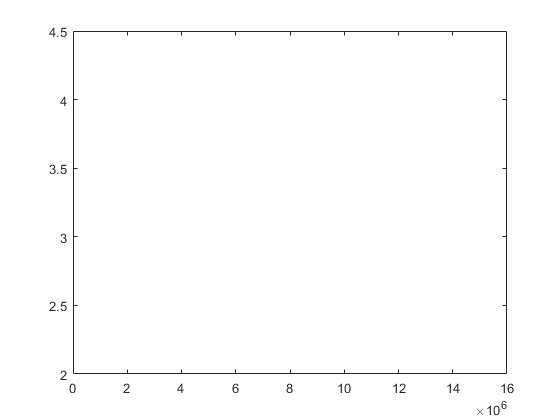


% load data
figure

for ii = 1:length(x)
    
    load(fullfile(savePath,x{ii,1}));
       
    rawdata{ii} = data.datensatz(:,1);
    
    fre(ii) = data.fn;
        
    M.var_m(ii,1) = var(data.datensatz(:,1));
    
    M.rms_m(ii,1) = rms(data.datensatz(:,1));
    
    M.mean_m(ii,1) = mean(data.datensatz(:,1));
    
    M.kurt_m(ii,1) = kurtosis(data.datensatz(:,1));
   
    M.p2r_m(ii,1) = peak2rms(data.datensatz(:,1));
   
    M.p2p_m(ii,1) = peak2peak(data.datensatz(:,1));
    
    M.quant_m(ii,1) = quantile(data.datensatz(:,1),0.5); 
    
    plot([0 16*10^6],M.var_m(ii,1))
end


save machinefeatures M

% elseif newload==0
%     load machinefeatures
% end

## Box Plot

% figure(1)
% rms_all_vec = reshape(M.rms_m);
% boxplot(M.rms_m);
% xlabel('Data Blocks')
% ylabel('Number of values in a box')
% title('RMS value analysis')

## Probability distribution

#### Histogram

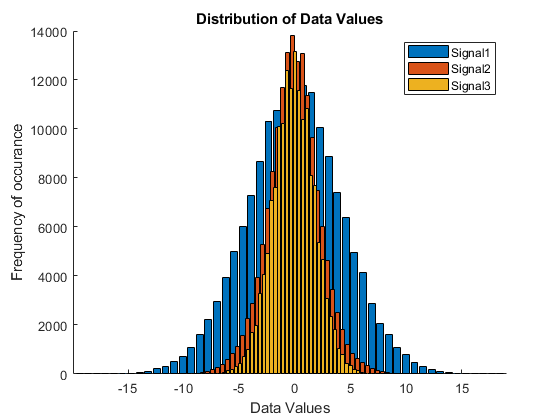

nclasses = 50;
figure
hold on
for ii = 1:length(x)
    
    [prob,center]=hist(rawdata{ii},nclasses);
    bar(center,prob, 'Displayname',['Signal' num2str(ii)]);
    % histogram(data.datensatz(:,1),nclasses)

end
    xlabel('Data Values');
    ylabel('Frequency of occurance');
    title('Distribution of Data Values');
    legend toggle
hold off

#### Probability Density Using Matlab Function

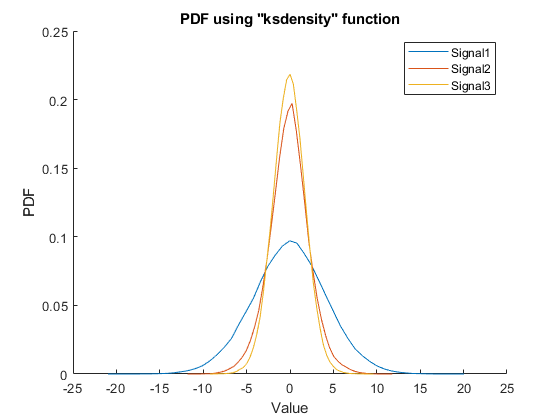

figure
hold on
for ii = 1:length(x)
    [PDF,center1]=ksdensity(rawdata{ii},'npoints',nclasses);
    plot(center1,PDF,'Displayname',['Signal' num2str(ii)]);
    xlabel('Value');
    ylabel('PDF');
    title('PDF using "ksdensity" function');
end
legend toggle
hold off

### Probability Density by Manual Calculation

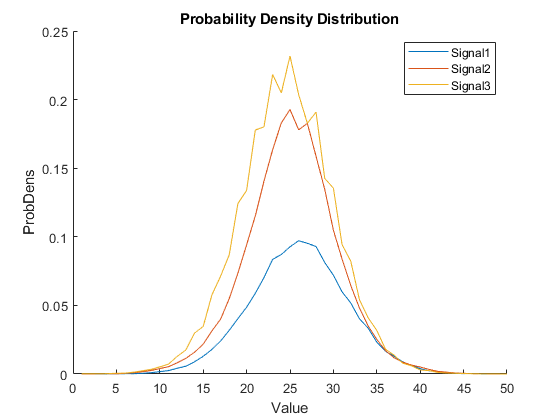

figure
hold on
for ii = 1:length(x)
    [prob,center]=hist(rawdata{ii},nclasses);
    probDens=prob/(length(rawdata{ii})*(center(2)-center(1)));
    plot(probDens,'Displayname',['Signal' num2str(ii)]);
    title('Probability Density Distribution');
    xlabel('Value');
    ylabel('ProbDens');
end
legend toggle
hold off

### Likelihood

% figure
% hold on
for ii = 1:length(x)
    likelihood = quantile(rawdata{ii},[0.05 0.25 0.5 0.75 0.95]);
%     title('Probability Density Distribution','Displayname',['Signal' num2str(ii)]);
%     xlabel('Value');
%     ylabel('ProbDens');
end
% legend toggle
% hold off

### CDF

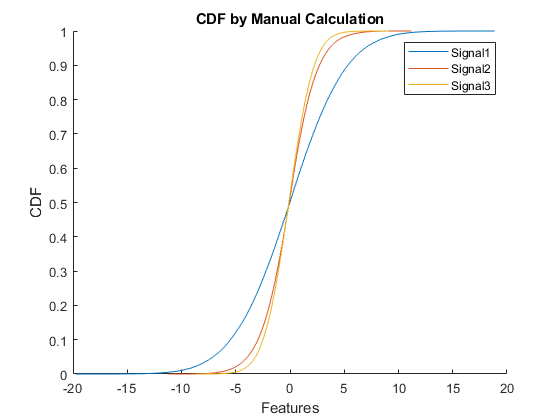

figure
hold on
for ii = 1:length(x)
    [dd,idx] = sort(rawdata{ii});
    X_ECDF = dd;
    Y_ECDF = (1/length(rawdata{ii})):(1/length(rawdata{ii})):1;
    plot(X_ECDF,Y_ECDF,'Displayname',['Signal' num2str(ii)]);
    xlabel('Features')
    ylabel('CDF')
    title('CDF by Manual Calculation')
end
legend toggle
hold off

### Correlation

% rhoSig12 = corrcoef(rawdata{1},rawdata{2});
% rhoSig23 = corrcoef(rawdata{2},rawdata{3});
% rhoSig13 = corrcoef(rawdata{1},rawdata{3});
% 
% plot(rawdata{1},rawdata{2})
% figure
% plot(rawdata{2},rawdata{3})
% figure
% plot(rawdata{2},rawdata{3})
% 
% std1 = std(rawdata{1})
% std2 = std(rawdata{2})
% % std12 =

#### Signals Data Points with respect to the Measurement Number

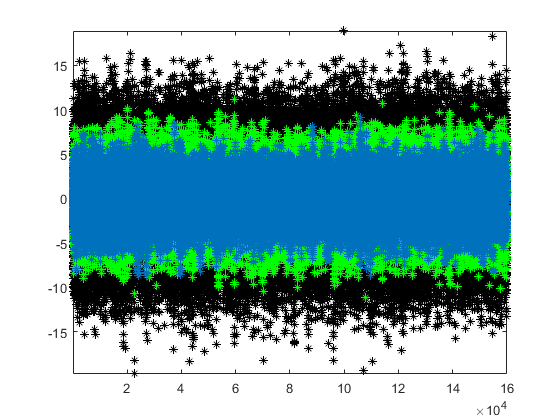

plot(rawdata{1},'*k')
hold on
% figure
plot(rawdata{2},'*g')
% figure
plot(rawdata{3},'*')
axis tight
hold off